% %PID Regler Entwurf

%           Werte setzten           %
R = 0.398/2

R = 0.1990

L = 876e-6/2; 
Ts =1e-5

Ts = 1.0000e-05

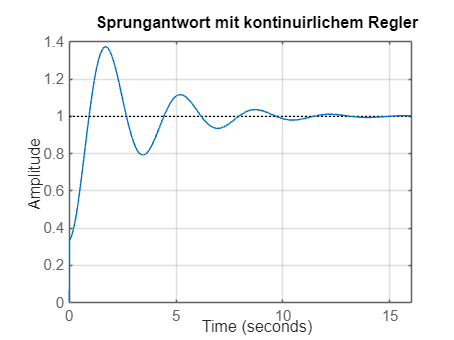

s = tf('s');
GS1 = 1/(2*s+1);
%           kontinuirlichem PID           %
% Regler: PID (automatisch abgestimmt)
GR1 = pid(1,10,1,1e-3);

% Geschlossener Kreis mit Einheitssensor
GRKI = feedback(GR1*GS1, 1);

% Sprungantwort plotten
figure; step(GRKI); grid on; title('Sprungantwort mit kontinuirlichem Regler');


% Kennwerte ausgeben
info = stepinfo(GRKI)

info = struct with fields:
         RiseTime: 0.8160
    TransientTime: 10.5047
     SettlingTime: 10.5047
      SettlingMin: 0.7920
      SettlingMax: 1.3732
        Overshoot: 37.3174
       Undershoot: 0
             Peak: 1.3732
         PeakTime: 1.6991


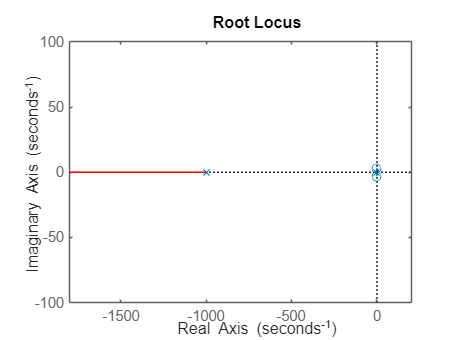


rlocus(GR1*GS1)


%           diskreter PID           %

% Discrete
GS1_D = c2d(GS1,Ts,'zoh')

GS1_D =
 
  5e-06
  -----
  z - 1
 
Sample time: 1e-05 seconds
Discrete-time transfer function.
Model Properties


GR1_D = c2d(GR1,Ts,'tustin')

GR1_D =
 
            Ts*(z+1)                 1         
  Kp + Ki * -------- + Kd * -------------------
            2*(z-1)         Tf+Ts/2*(z+1)/(z-1)

  with Kp = 1, Ki = 10, Kd = 1, Tf = 0.001, Ts = 1e-05
 
Sample time: 1e-05 seconds
Discrete-time PIDF controller in parallel form.
Model Properties


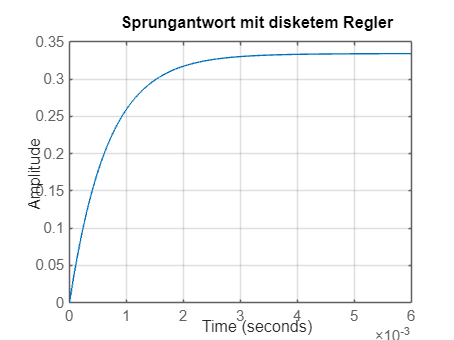


GRKI_D = feedback(GR1_D*GS1_D, 1);

% Sprungantwort plotten
figure; step(GRKI_D); grid on; title('Sprungantwort mit disketem Regler');


% Kennwerte ausgeben
info = stepinfo(GRKI_D)

info = struct with fields:
         RiseTime: 0.0015
    TransientTime: 0.0027
     SettlingTime: 0.0027
      SettlingMin: 0.3018
      SettlingMax: 0.3348
        Overshoot: 0
       Undershoot: 0
             Peak: 0.3348
         PeakTime: 0.0104


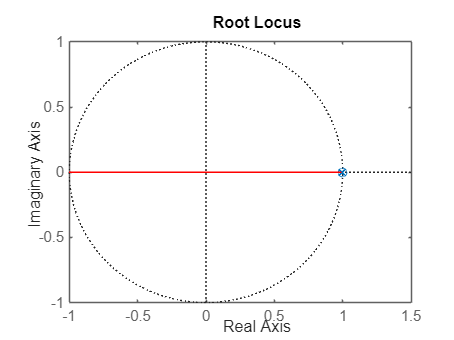


rlocus(GR1_D*GS1_D)

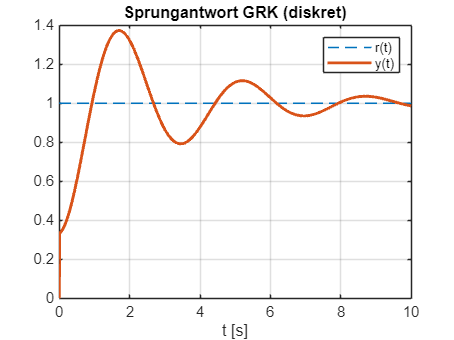



N = 1000000;
t = (0:N-1)' * Ts;

w = ones(N,1);               % Eingang (Sprung)
y = lsim(GRKI_D, w, t);      % Ausgang

figure;
plot(t, w, '--'); hold on;
plot(t, y, 'LineWidth', 2);
grid on;
xlabel('t [s]');
legend('r(t)', 'y(t)');
title('Sprungantwort GRK (diskret)');


% Tabelle mit Spaltennamen
T = table(t, w, y, 'VariableNames', {'time', 'w', 'y'});

% CSV schreiben (Header + ; als Trennzeichen)
filename = "GRK_input_output_pidf.csv";

try
    % Falls deine MATLAB-Version es unterstützt:
    writetable(T, filename, "Delimiter", ";", "DecimalSeparator", ",");
catch
    % Fallback: erst normal schreiben, dann Punkt -> Komma ersetzen
    writetable(T, filename, "Delimiter", ";");

    txt = fileread(filename);
    txt = strrep(txt, ".", ",");
    fid = fopen(filename, "w");
    fwrite(fid, txt);
    fclose(fid);
end

disp("✅ CSV gespeichert: " + filename);

✅ CSV gespeichert: GRK_input_output_pidf.csv
